# Human Activity Recognition Using Mobile Phone Data - Classification

Supervised learning example. Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing different activities (walking, lying, sitting etc). The goal of this example is to provide a strategy to build a classifier that can automatically identify the activity type given the sensor measurements.

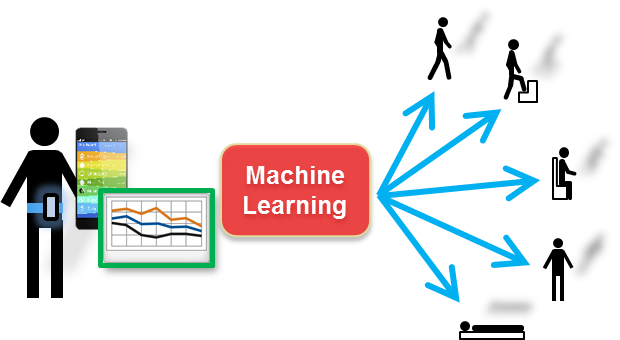

The dataset is courtesy of: Davide Anguita, Alessandro Ghio, Luca Oneto, Xavier Parra and Jorge L.  Reyes-Ortiz. 

Human Activity Recognition on Smartphones using a Multiclass Hardware-Friendly Support Vector Machine. International

Workshop of Ambient Assisted Living (IWAAL 2012). Vitoria-Gasteiz, Spain. Dec 2012.

Detailed Information about the Dataset: 

[https://archive.ics.uci.edu/ml/datasets/human+activity+recognition+using+smartphones](https://archive.ics.uci.edu/ml/datasets/human+activity+recognition+using+smartphones) 

This code is based on Rohit Agrawal’s Lunch & Learn Webinar Series with MATLAB Fridays for Lithuanian Universities.

## Record human activity data from your smartphone (optional)

- Use MATLAB Mobile app to record accelerometer data while doing different activities.

- Load the data to MATLAB or optionally use the sensorlog.  

- Plot the data and identify which part of the data corresponds to what activity.  

- Hint - the data was recorded while sitting, walking and running. 

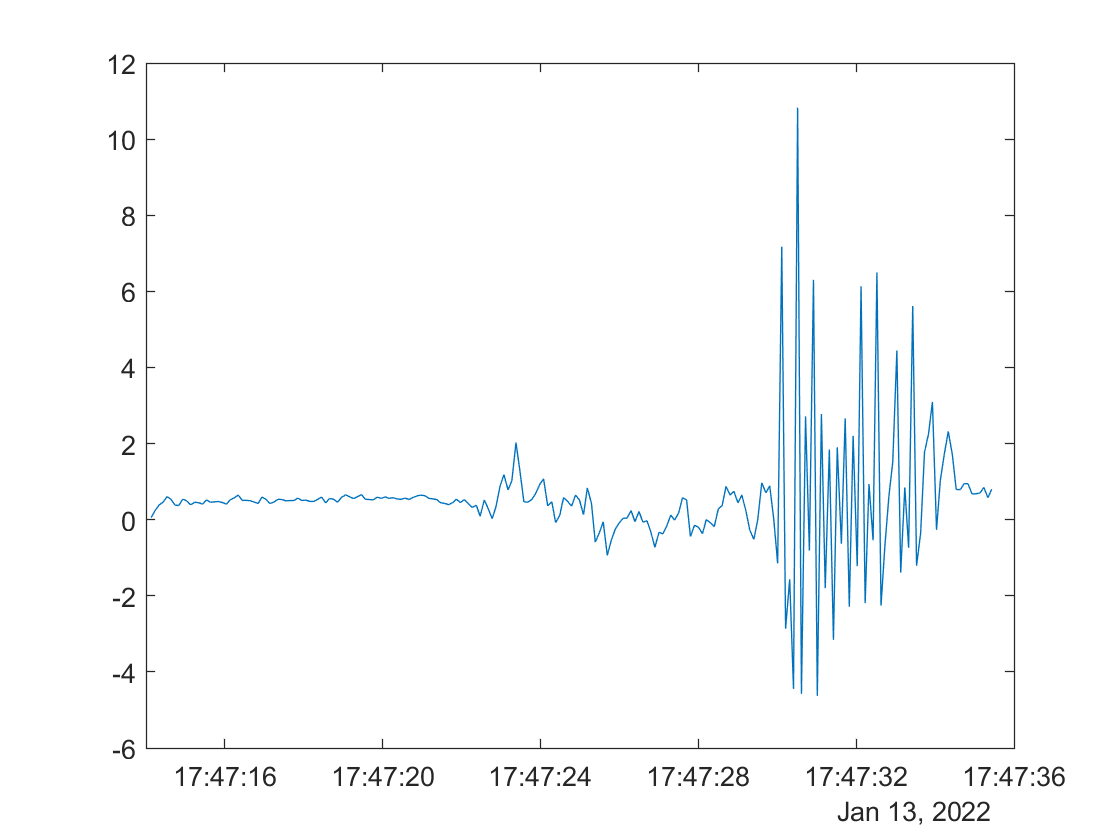

load sensorlog_20220113_174714.mat
plot(Acceleration.Timestamp,Acceleration.X)

## 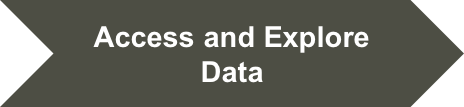

## Load Raw Sensor Data for Training

Data has been split and stored into two MAT files, one for training and one for testing. See data folder for addtional info on original files. 

Load raw data for training. The file contains 3-axial accelerometor and 3-axial gyroscope measurements for a total of 7352 subject activities recorded.

%addpath(genpath(pwd));
load rawSensorData_train.mat

## Display Data Summary

Display the original sensor data.

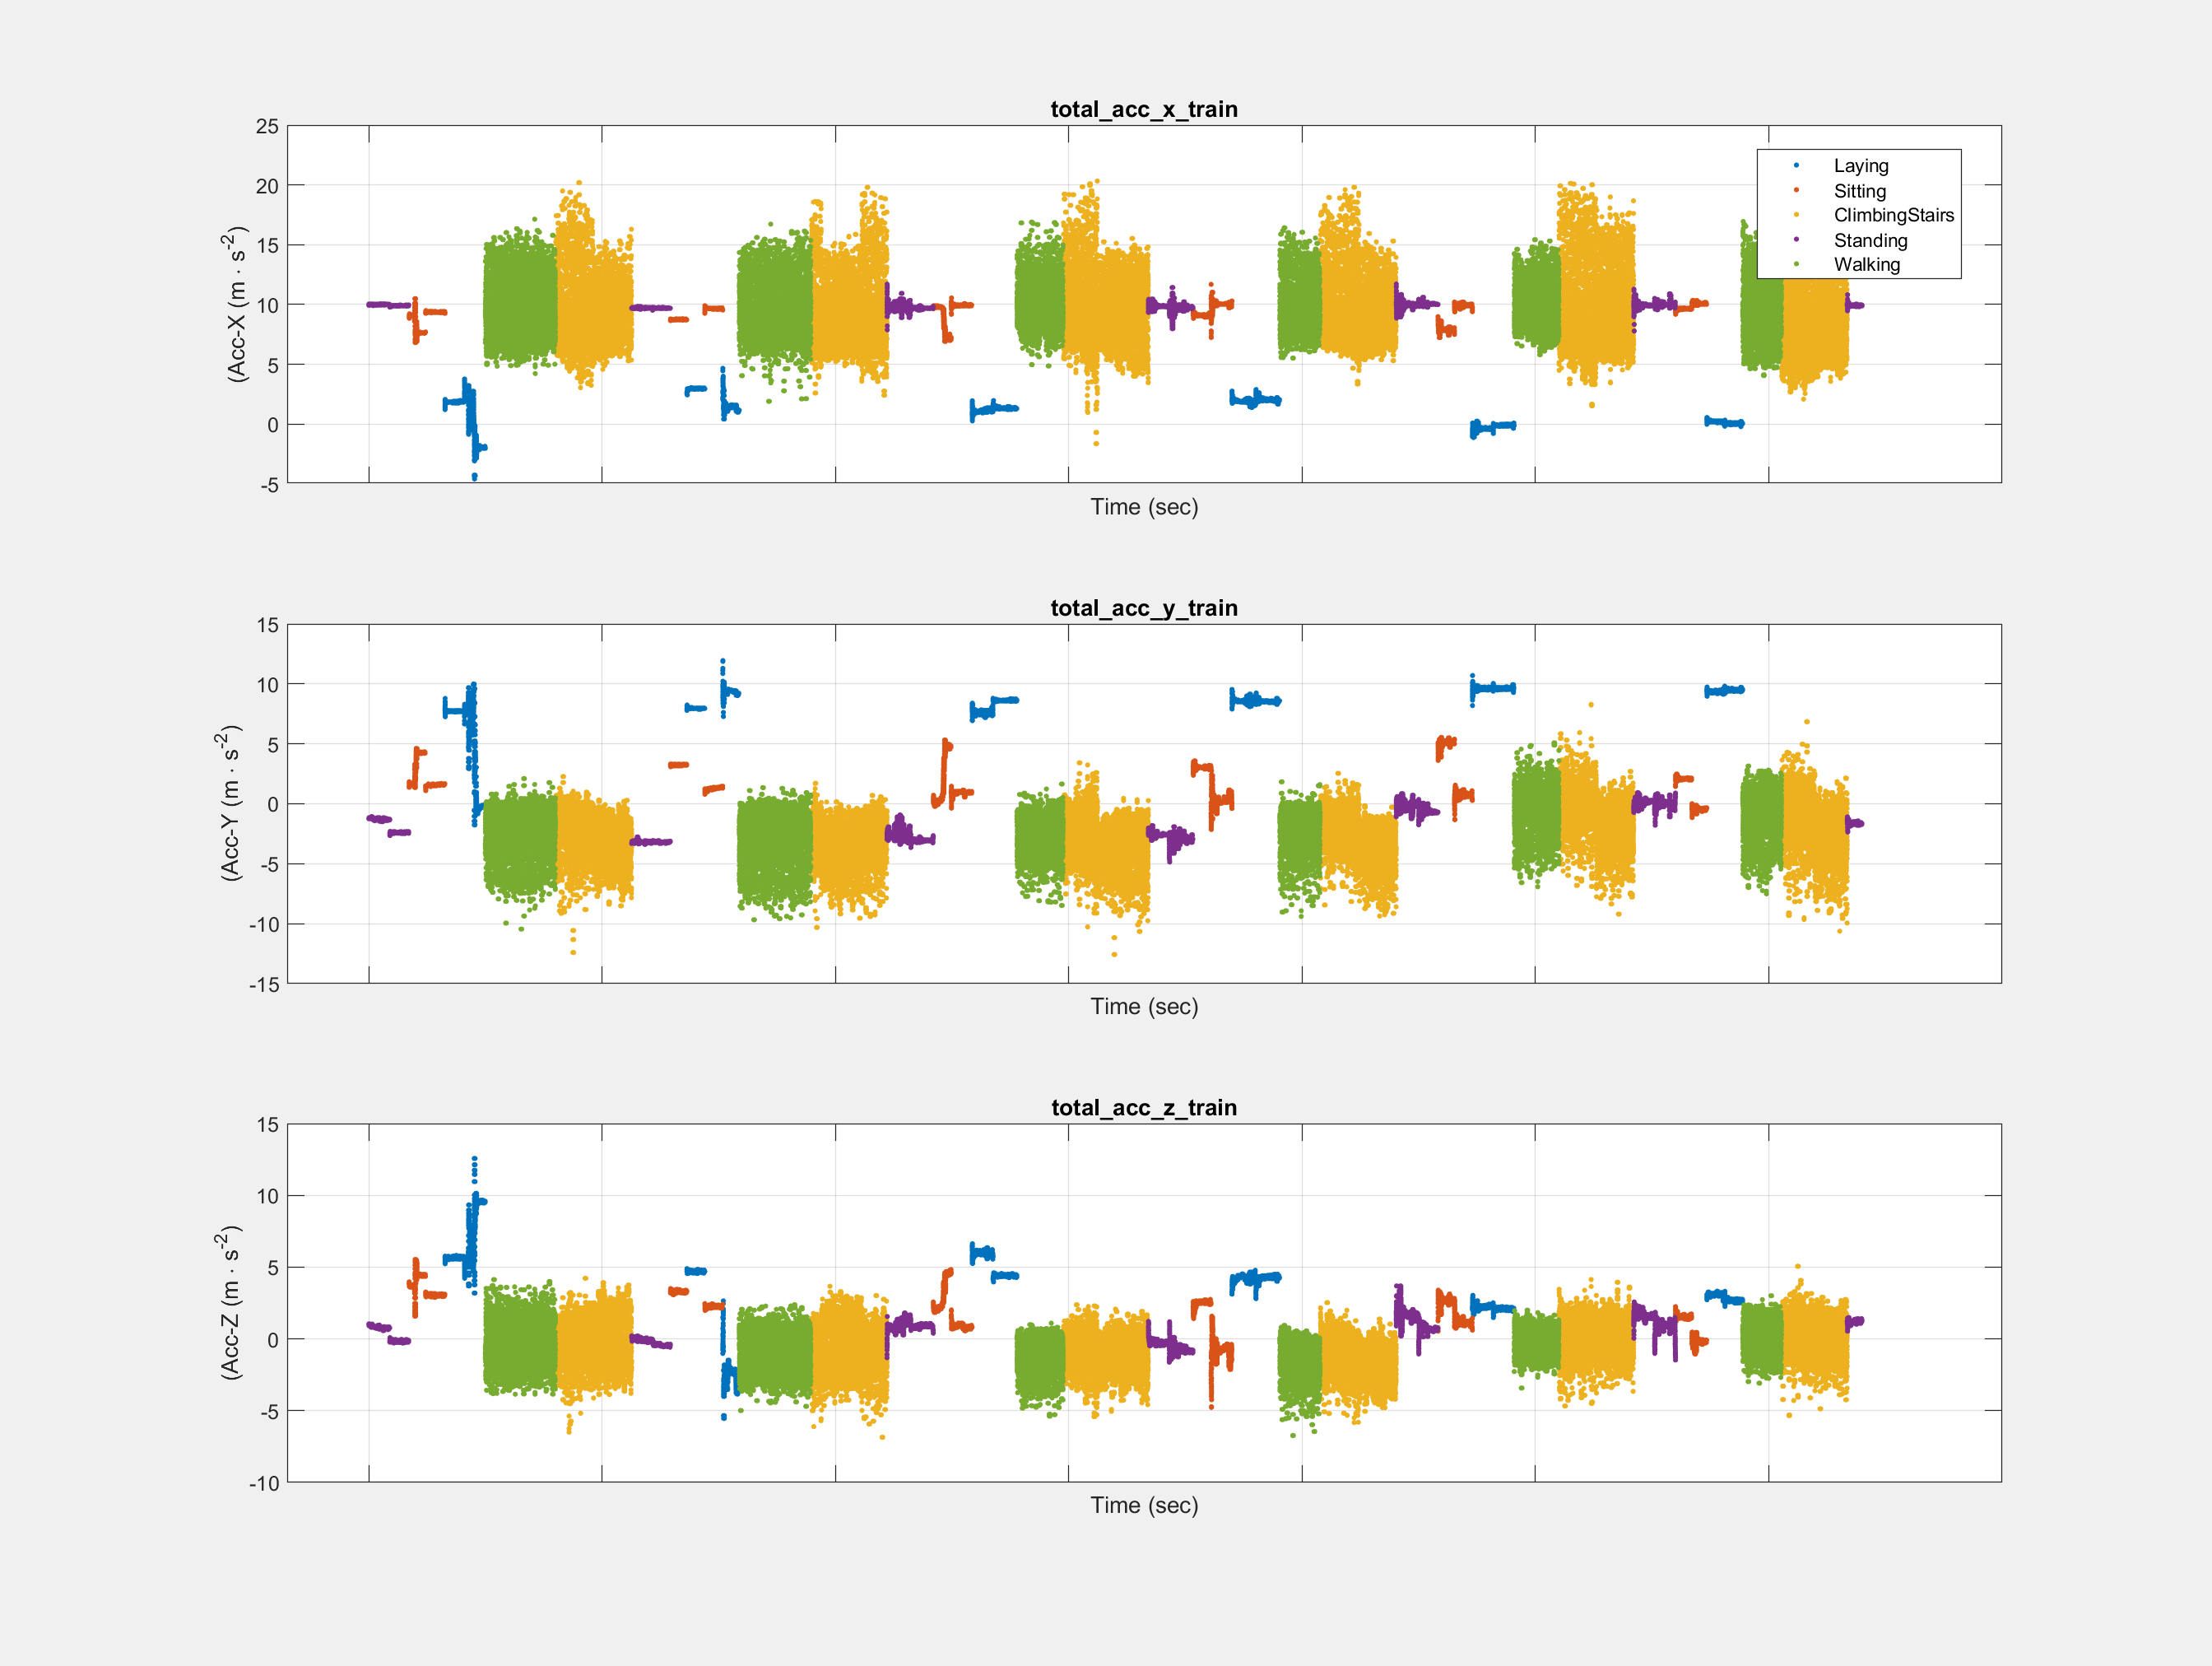

plotRawSensorData(total_acc_x_train,total_acc_y_train,total_acc_z_train,trainActivity,1000);

## 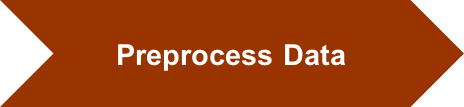

## Create Table Variable

Tables facilitate easy manipulation of lots of variables. Concatenate everything into a table.

rawSensorDataTrain = table(total_acc_x_train, total_acc_y_train, total_acc_z_train, body_gyro_x_train, body_gyro_y_train, body_gyro_z_train);

## Pre-process Training Data: **Feature Extraction. **

The sensor data contain windows of 2.56sec (128 readings/window) Lets start with a simple average feature for every 128 points

T_mean = varfun(@rowmean, rawSensorDataTrain);
T_stdv = varfun(@rowstd, rawSensorDataTrain);

Optionally, use [diagnostic feature designer](https://in.mathworks.com/help/predmaint/gs/import-and-visualize-data-in-diagnostic-feature-designer.html#:~:text=Diagnostic%20Feature%20Designer%20is%20an,a%20system%20under%20varying%20conditions.) app to extract many time and frequency domain features interactively (requires predictive maintenance toolbox). To open this prompt, run

`diagnosticFeatureDesigner`

% Build new table
humanActivityData = [T_mean, T_stdv];
humanActivityData.activity = trainActivity;
humanActivityData

humanActivityData = 7352×13 table
    rowmean_total_acc_x_train    rowmean_total_acc_y_train    rowmean_total_acc_z_train    rowmean_body_gyro_x_train    rowmean_body_gyro_y_train    rowmean_body_gyro_z_train    rowstd_total_acc_x_train    rowstd_total_acc_y_train    rowstd_total_acc_z_train    rowstd_body_gyro_x_train    rowstd_body_gyro_y_train    rowstd_body_gyro_z_train    activity
    _________________________    _________________________    _________________________    _________________________    _________________________    _________________________    ________________________    ________________________    ____________

## 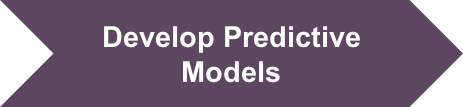 

## Train, compare and select classifier 

Use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers

%classificationLearner

or load previously trained classifier.

trainedClassifier_structure = trainKNNAppClassifier(humanActivityData);
trainedClassifier = trainedClassifier_structure.ClassificationKNN

## Load Raw Sensor Data for Testing

Load test data set.

load rawSensorData_test.mat

## Test classifier performance on new data

Step 1: Create a table

rawSensorDataTest = table(...

trainedClassifier =   ClassificationKNN
           PredictorNames: {1×12 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Laying    Sitting    ClimbingStairs    Standing    Walking]
           ScoreTransform: 'none'
          NumObservations: 7352
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


    total_acc_x_test, total_acc_y_test, total_acc_z_test, ...
    body_gyro_x_test, body_gyro_y_test, body_gyro_z_test);


Step 2: Extract features from raw sensor data

T_mean = varfun(@rowmean, rawSensorDataTest);
T_stdv = varfun(@rowstd, rawSensorDataTest);

humanActivityDataTest = [T_mean, T_stdv];
humanActivityDataTest.activity = testActivity;

Step 3: Use trained model to predict activity on new sensor data

plotActivityResults(trainedClassifier,rawSensorDataTest,humanActivityDataTest,0.05)

Step 4: Plot and calculate accuracy

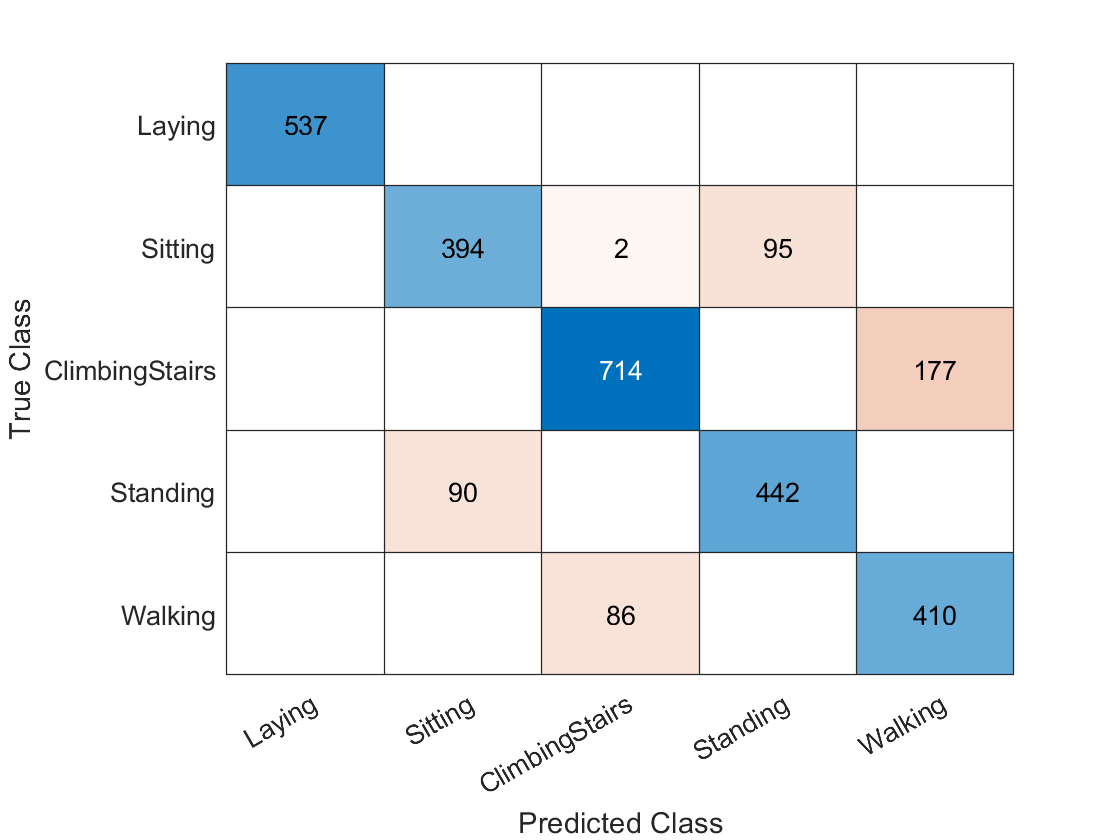

accuracy =    0.847302341364099


figure;
predictedActivity = predict(trainedClassifier, humanActivityDataTest{:, 1:end-1});
confusionchart(humanActivityDataTest{:, end}, predictedActivity)
accuracy = sum(humanActivityDataTest{:, end} == predictedActivity) / height(humanActivityDataTest)